# Modeling Mird Migration as a Flow

% *Load data*

clear all;
load('data/Density_inference.mat','data');
load('data/Density_estimationMap','g');
load('data/Flight_estimationMap','guv');
addpath('./functions/')
load coastlines;
col2=colormap(brewermap([],'Paired'));

load('G:/Raphael_temp/Density_simulationMap_reassemble');

dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]); %dlat
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]); % dlon
area = repmat(dx*dy,1,g.nlon);

**Build Grid**

gext.lat = fillmissing([nan(1,1) ;g.lat ;nan(1,1)],'linear');
gext.lon = fillmissing([nan(1,1); g.lon; nan(1,1)],'linear');
gext.nlat = numel(gext.lat);
gext.nlon = numel(gext.lon);
[gext.lat2D, gext.lon2D] = ndgrid(gext.lat,gext.lon);

gext.time = sort( [g.time; g.day-.5]);

gext.nt = numel(gext.time);
gext.day_id=nan(gext.nt,1);
gext.day_id(ismember(gext.time,g.time)) = g.day_id;
gext.day_id(isnan(gext.day_id)) = gext.day_id(find(isnan(gext.day_id))+1);
tmp=nan(g.nlm,gext.nt);
tmp(:,ismember(gext.time,g.time)) = g.NNT;
gext.NNT=nan(gext.nlat,gext.nlon,gext.nt);
gext.NNT(padarray(repmat(g.latlonmask,1,1,gext.nt),[1 1 0], false))=tmp;
gext.mask_day = logical(gext.NNT>-1 & gext.NNT<1);
gext.time_b=nan(gext.nt,1);
gext.time_b(ismember(gext.time,g.time)) = g.time_b;
gext.latlonmask = padarray(g.latlonmask,[1 1],false);


dxext = fillmissing([NaN;dx;NaN],'linear');
areaext = fillmissing(padarray(area,[1 1],nan),'linear',1);
areaext = fillmissing(areaext,'linear',2);

dt=15/60;

% *Compute flight speed and density*

vy = nan(g.nlat, g.nlon, gext.nt); vx=vy;
tmp = repmat(g.latlonmask,1,1,gext.nt); 
tmp(:,:,ismember(gext.time,g.day-.5))=false;
vy(tmp) = guv.v_est/1000*60*60; % m/s -> km/h (+) north, (-) south
vx(tmp) = guv.u_est/1000*60*60; % m/s -> km/h (+) east, (-) west

% * Transect definition*
transect_name={'North', 'East', 'Alpes', 'Spain' ,'Altlantic','England'};
transect(:,:,1)= [42 51 ; 43 82];
transect(:,:,2)= [20 45 ; 78 87];
transect(:,:,3)= [1 19 ; 40 84];
transect(:,:,4)= [1 9; 1 39];
transect(:,:,5) = [5 24; 1 18];
transect(:,:,6)= [25 43 ; 1 45];
sec_col={'r','b','y','g','c','k'};
cat_trans=zeros(gext.nlat,gext.nlon);
for i_s=1:numel(transect_name)
    cat_trans(transect(1,1,i_s):transect(1,2,i_s),transect(2,1,i_s):transect(2,2,i_s))=i_s;
end

## Compute for each realization

nb_real = size(real_dens,4);

Ts_day_landing=nan(g.nat,nb_real);
Ts_day_takingoff=nan(g.nat,nb_real);
Ts_Fout_day_entering=nan(g.nat,nb_real);
Ts_Fout_day_leaving=nan(g.nat,nb_real);

Fout_sec_season=nan(numel(transect_name),4,nb_real);

nightly_i_t=52:55;
nightly_W_takingoff=nan(g.nlat,g.nlon,numel(i_t),nb_real);
nightly_W_landing = nightly_W_takingoff;
nightly_dens = nightly_W_takingoff;

seasonal_W_takingoff = nan(g.nlat,g.nlon,nb_real,2);
seasonal_W_landing = seasonal_W_takingoff;

knownday = ismember(datenum(g.day), unique(data.day(data.day_id)));

for i_real = 1:nb_real
    
    disp(i_real)
    tmp = real_dens(:,:,:,i_real);
    % remove for rain
    tmp(g.rain(repmat(g.latlonmask,1,1,g.nt))>data.mask_rain_thr) = 0;
    
    rho = nan(g.nlat, g.nlon, gext.nt);
    rho(:,:,~ismember(gext.time,g.day-.5)) = tmp;
    
    rho0 = rho;
    rho0(isnan(rho)) = 0; % bird/km^2

    % *Compute the Fluxes*

    Phiy_pad = padarray(rho .* vy .* repmat(dx,1,g.nlon,gext.nt) ,[1 0 0],nan); % bird/km^2 * km/h *km ->  bird/h
    Phix_pad = padarray(rho .* vx .* dy,[0 1 0],nan);

    Phiy_h = movmean(Phiy_pad,[0 1],1,'omitnan','Endpoints','discard'); 
    Phix_h = movmean(Phix_pad,[0 1],2,'omitnan','Endpoints','discard');

    Phiy_h_0=padarray(Phiy_h,[1 1 0],0);
    Phix_h_0=padarray(Phix_h,[1 1 0],0);

    Phiy_h_0(isnan(Phiy_h_0))=0;
    Phix_h_0(isnan(Phix_h_0))=0;

    dPhiy = diff(Phiy_h_0,1,1);
    dPhix = diff(Phix_h_0,1,2);

    F = (dPhiy + dPhix ).*dt; % bird/h * hr -> bird

    Fin = F; 
    % Fin(~gext.mask_day)=0;
    Fin(repmat(~gext.latlonmask,1,1,gext.nt)) = 0;

    Fout = F;
    % Fout(gext.mask_day)=0;
    Fout(repmat(gext.latlonmask,1,1,gext.nt)) = 0;

    W = diff(rho0 .* repmat(area,1,1,gext.nt),1,3) + Fin(2:end-1,2:end-1,1:end-1);

    
    % *Aggregate the Fluxes*
    
    % Separate the landing/takingoff
    W_landing=W; W_takingoff=W;
    W_landing(W_landing>=0)=0;
    W_landing2 = W.landing; W_landing2(~gext.mask_day(2:end-1,2:end-1,1:end-1))=0;
    W_takingoff(W_takingoff<=0)=0;
    
    % Separating entering and leaving
    Fout_leaving=Fout; Fout_entering=Fout;
    Fout_leaving(Fout_leaving>=0)=0;
    Fout_entering(Fout_entering<=0)=0;

    % Compute daily sum
    W_day_takingoff=nan(g.nlat,g.nlon,g.nat);
    W_day_landing=nan(g.nlat,g.nlon,g.nat);
    W_day_landing2=nan(g.nlat,g.nlon,g.nat);
    Fout_day_entering=nan(gext.nlat,gext.nlon,g.nat);
    Fout_day_leaving=nan(gext.nlat,gext.nlon,g.nat);
    for i_t=1:g.nat-1
        idt=gext.day_id(1:end-1)==i_t;
        W_day_takingoff(:,:,i_t)=nansum(W_takingoff(:,:,idt),3);
        W_day_landing(:,:,i_t)=nansum(W_landing(:,:,idt),3);
        W_day_landing2(:,:,i_t)=nansum(W_landing2(:,:,idt),3);
        Fout_day_entering(:,:,i_t)=nansum(Fout_entering(:,:,idt),3);
        Fout_day_leaving(:,:,i_t)=nansum(Fout_leaving(:,:,idt),3);
    end
    W_day_takingoff(W_day_takingoff==0)=nan;
    W_day_landing(W_day_landing==0)=nan;
    W_day_landing2(W_day_landing2==0)=nan;


    % *Compute timeseries*
    Ts_day_landing(:,i_real) = reshape(nansum(nansum(W_day_landing,1),2),1,[]);
    Ts_day_takingoff(:,i_real) = reshape(nansum(nansum(W_day_takingoff,1),2),1,[]);
    Ts_Fout_day_entering(:,i_real) = reshape(nansum(nansum(Fout_day_entering,1),2),1,[]);
    Ts_Fout_day_leaving(:,i_real) = reshape(nansum(nansum(Fout_day_leaving,1),2),1,[]);


    % * Fluxes per transect*
    Fout_sec=nan(g.nat,numel(transect_name),2);
    for i_s=1:numel(transect_name)
        Fout_sec(:,i_s,1) = sum(reshape(Fout_day_entering(repmat(cat_trans==i_s,1,1,g.nat)),[],g.nat));
        Fout_sec(:,i_s,2) = sum(reshape(Fout_day_entering(repmat(cat_trans==i_s,1,1,g.nat)),[],g.nat));
    end
    
    % Flux per season
    Fout_sec_season(:,1,i_real)=nansum(Fout_sec(knownday&g.day<datetime('2018-07-01'),:,1));
    Fout_sec_season(:,2,i_real)=nansum(Fout_sec(knownday&g.day<datetime('2018-07-01'),:,2));
    Fout_sec_season(:,3,i_real)=nansum(Fout_sec(knownday&g.day>datetime('2018-07-01'),:,1));
    Fout_sec_season(:,4,i_real)=nansum(Fout_sec(knownday&g.day>datetime('2018-07-01'),:,2));
    
    
    % * Nighly Fluxes*
    for i_tt=1:numel(nightly_i_t)
        nightly_W_takingoff(:,:,i_tt,i_real)=nansum(W_day_takingoff(:,:,nightly_i_t(i_tt)),3);
        nightly_W_landing(:,:,i_tt,i_real)=nansum(W_day_landing2(:,:,nightly_i_t(i_tt)),3);
        nightly_dens(:,:,i_tt,i_real)=nanmean(real_dens(:,:,nightly_i_t(i_tt)==g.day_id,i_real),3);
    end
    

    % * Seasonal Flow : within *
    id = g.day<datetime('2018-07-01');
    seasonal_W_takingoff(:,:,i_real,1)=nansum(W_day_takingoff(:,:,id),3);
    seasonal_W_landing(:,:,i_real,1)=nansum(W_day_landing2(:,:,id),3);
    %seasonal_W_W(:,:,i_real,1)=nansum(W_day_W(:,:,id),3);
    id = g.day>datetime('2018-07-01');
    seasonal_W_takingoff(:,:,i_real,2)=nansum(W_day_takingoff(:,:,id),3);
    seasonal_W_landing(:,:,i_real,2)=nansum(W_day_landing2(:,:,id),3);
    

end

     1



Unable to perform assignment because the size of the left side is 15310-by-1 and the size of the right side is 374-by-15310.

Ts_day_landing(~knownday,:)=nan;
Ts_day_takingoff(~knownday,:)=nan;
Ts_Fout_day_leaving(~knownday,:)=nan;
Ts_Fout_day_entering(~knownday,:)=nan;

nightly_W_takingoff(nightly_W_takingoff==0)=NaN;
nightly_W_landing(nightly_W_landing==0)=NaN;
nightly_dens(nightly_dens==0)=NaN;

seasonal_W_landing(seasonal_W_landing==0)=NaN;
seasonal_W_takingoff(seasonal_W_takingoff==0)=NaN;

## Save

%save('data/SinkSourceSim.mat','Ts_day_landing','Ts_day_takingoff','Ts_Fout_day_leaving','Ts_Fout_day_entering','Fout_sec_season','nightly_W_takingoff','nightly_W_landing','nightly_dens','seasonal_W_landing','seasonal_W_takingoff');
%load('data/SinkSourceSim.mat')

## Results

## Nightly migratory pulses and stopovers

Choose a simulation

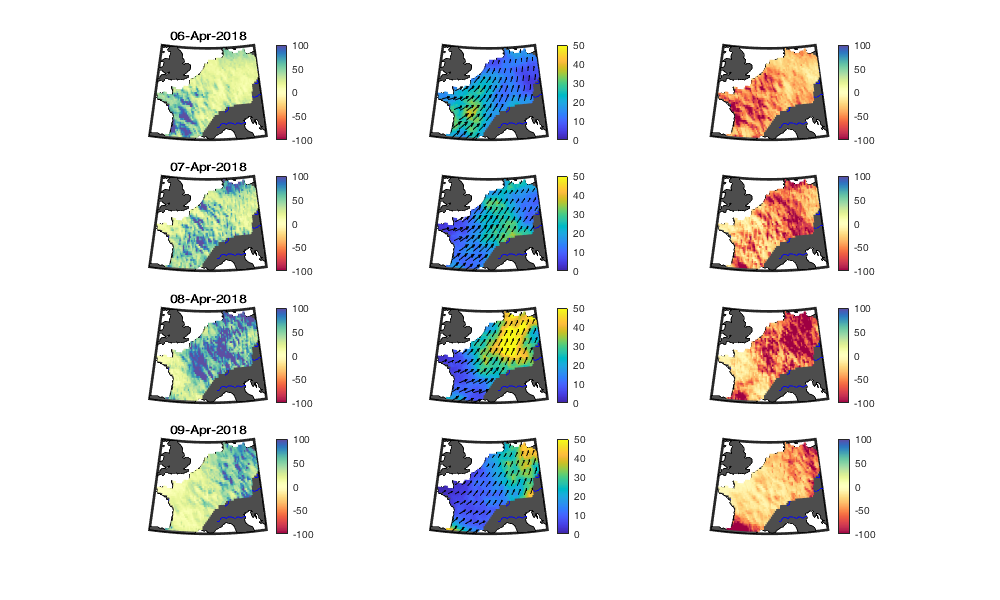

i_real = 56;
quiv_fac = 15;
figure('position',[0 0 1000 600]); 
i_t=52:55;
for i_tt=1:numel(i_t)
    for i2=1:3
        subplot(numel(i_t),3,3*(i_tt-1)+i2); hold on
        h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); geoshow('worldrivers.shp','Color', 'blue')
        caxis([-100 100])
        if i2==1
            % W_tmp=nightly_W_takingoff(:,:,i_tt,i_real)./area;
            W_tmp=mean(nightly_W_takingoff(:,:,i_tt,:),4)./area;
            title(datestr(g.day(i_t(i_tt))))
            colormap(gca,brewermap([],'Spectral'))
        elseif i2==2
            % W_tmp=nightly_dens(:,:,i_tt,i_real); 
            W_tmp=mean(nightly_dens(:,:,i_tt,:),4); 
            caxis([0 50])
        elseif i2==3
            % W_tmp=nightly_W_landing(:,:,i_tt,i_real)./area;
            W_tmp=mean(nightly_W_landing(:,:,i_tt,:),4)./area;
            colormap(gca,brewermap([],'Spectral'))
        end
        surfm(g.lat2D,g.lon2D,W_tmp ); colorbar 
        
        if i2==2
            gu_tmp = nan(g.nlat, g.nlon); gv_tmp = nan(g.nlat, g.nlon);
            gu_tmp(g.latlonmask)=nanmean(guv.u_est(:,i_t(i_tt)==g.day_id),2);
            gu_tmp(gu_tmp==0)=NaN;
            gv_tmp(g.latlonmask)=nanmean(guv.v_est(:,i_t(i_tt)==g.day_id),2);
            gv_tmp(gv_tmp==0)=NaN;
            quiverm(g.lat2D(1:5:end,1:5:end),g.lon2D(1:5:end,1:5:end),gu_tmp(1:5:end,1:5:end)/quiv_fac,gv_tmp(1:5:end,1:5:end)/quiv_fac,'k',0)
        end
    end
end    

## Year-round accumulation of migratory birds on the ground

Times serie daily

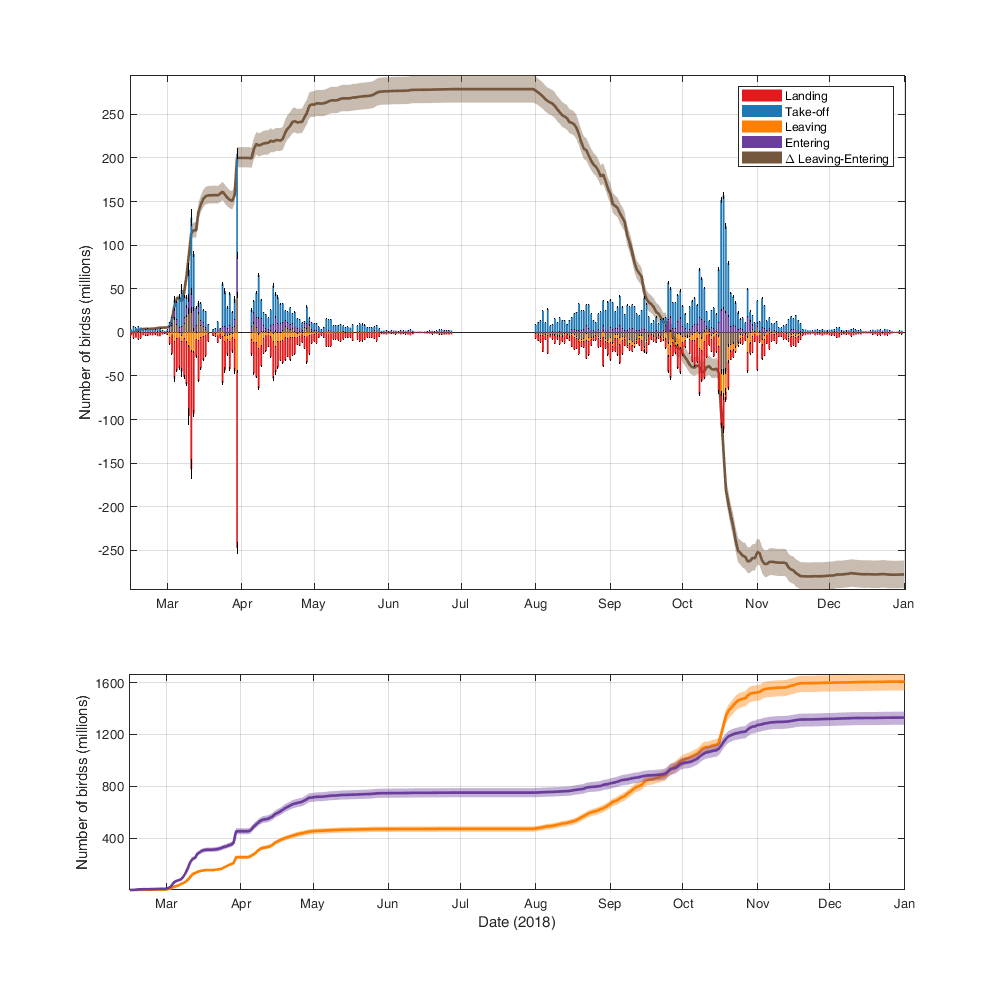

figure('position',[0 0 1000 1000]); subplot(3,1,[1 2]); box on; grid on
hold on; ylabel('Number of birdss (millions)')

% fill(datenum([g.day(1); g.day; g.day(end)]),[0 cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan') 0],'k','FaceAlpha',0.2);
tmp =[quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.05,2) ; flipud(quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.95,2))];
fill(datenum([g.day; flipud(g.day)]),tmp,[117 87 61]/255,'FaceAlpha',0.4,'EdgeColor','none');
plot(datenum(g.day),mean(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),2),'Color',[117 87 61]/255,'linewidth',2 ,'DisplayName','Cumulative \Delta takingoff/landing = # on the ground');
%plot(datenum(g.day),quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.05,2),'Color',[117 87 61]/255,'linewidth',1)
%plot(datenum(g.day),quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.95,2),'Color',[117 87 61]/255,'linewidth',1)

tmp_TS = cat(3,Ts_day_landing,Ts_day_takingoff,Ts_Fout_day_leaving,Ts_Fout_day_entering,Ts_Fout_day_leaving+Ts_Fout_day_entering);
tmp_col = {col2(6,:), col2(2,:),col2(8,:), col2(10,:) [117 87 61]/255};
clear h
for i=1:size(tmp_TS,3)
    tmp = tmp_TS(:,:,i)/1000000;
    h(i)=bar(datenum(g.day),nanmean(tmp,2),'FaceColor',tmp_col{i});
    errorbar(datenum(g.day),nanmean(tmp,2),nanmean(tmp,2)-quantile(tmp,0.05,2),nanmean(tmp,2)-quantile(tmp,0.95,2),'LineStyle','none','Color','k','LineWidth',0.5,'CapSize',0);   
end
legend(h,{'Landing','Take-off','Leaving','Entering','\Delta Leaving-Entering'});
datetick('x'); axis tight; %legend([h2 h3 h4 h5 h6 h1]);

subplot(3,1,3); box on; grid on
hold on; ylabel('Number of birdss (millions)')
%h1=fill(datenum([g.day ;flipud(g.day)]),-[cumsum((Ts.Fout.day.leaving)/1000000,'omitnan') fliplr(cumsum(-(Ts.Fout.day.entering)/1000000,'omitnan'))],'k','FaceAlpha',0.2,'DisplayName','Difference');
tmp =[quantile(cumsum(-(Ts_Fout_day_leaving)/1000000,'omitnan'),0.05,2) ; flipud(quantile(cumsum(-(Ts_Fout_day_leaving)/1000000,'omitnan'),0.95,2))];
fill(datenum([g.day; flipud(g.day)]),tmp,col2(8,:),'FaceAlpha',0.4,'EdgeColor','none');
plot(datenum(g.day),mean(cumsum(-(Ts_Fout_day_leaving)/1000000,'omitnan'),2),'Color',col2(8,:),'linewidth',2 ,'DisplayName','Cumulative Leaving');
tmp =[quantile(cumsum((Ts_Fout_day_entering)/1000000,'omitnan'),0.05,2) ; flipud(quantile(cumsum((Ts_Fout_day_entering)/1000000,'omitnan'),0.95,2))];
fill(datenum([g.day; flipud(g.day)]),tmp,col2(10,:),'FaceAlpha',0.4,'EdgeColor','none');
plot(datenum(g.day),mean(cumsum((Ts_Fout_day_entering)/1000000,'omitnan'),2),'Color',col2(10,:),'linewidth',2 ,'DisplayName','Cumulative Entering');
datetick('x'); xlabel('Date (2018)'); axis tight; yticks(0:400:1600) %legend([h2 h3 h1]);

## Statistics

function to help

fmeanq5q90 = @(x) [num2str(round(mean(x))) 'M (' num2str(round(quantile(x,0.05))) '-' num2str(round(quantile(x,0.95))) ')'];

Maximum Number of bird in a night

[max_takeoff,tmp] = max(Ts_day_takingoff(g.day<datetime('15-July-2018'),:));
assert(all(diff(tmp)==0),'Different day for max taking-off')
disp(['Maximum number of bird taking-off is: ' fmeanq5q90(max_takeoff/1000000) ' happening on the ' datestr(median(g.day(tmp))) '.'])

Maximum number of bird taking-off is: 205M (198-212) happening on the 30-Mar-2018.


[max_takeoff,tmp] = max(Ts_day_takingoff(g.day>datetime('15-July-2018'),:));
%assert(all(diff(tmp)==0),'Different day for max taking-off')
disp(['Maximum number of bird taking-off is: ' fmeanq5q90(max_takeoff/1000000) ' happening on the ' datestr(median(g.day(tmp))) '.'])

Maximum number of bird taking-off is: 157M (152-162) happening on the 19-May-2018.


How many night to reach 50% of all derpature

tmp = Ts_day_takingoff(g.day<datetime('15-July-2018')& all(~isnan(Ts_day_takingoff),2),:);
tmp = sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5);
disp(['50% of all bird taking-off in Spring happened in ' num2str(mean(tmp)) ' (SD=' num2str(std(tmp)) ') '])

50% of all bird taking-off in Spring happened in 17.03 (SD=0.17145) 


tmp = Ts_day_takingoff(g.day>datetime('15-July-2018')& all(~isnan(Ts_day_takingoff),2),:);
tmp=sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5);
disp(['50% of all bird taking-off in Autumn happened in ' num2str(mean(tmp)) ' (SD=' num2str(std(tmp)) ') '])

50% of all bird taking-off in Autumn happened in 28.86 (SD=0.34874) 


tmp = Ts_day_takingoff( ~isnan(Ts_day_takingoff'));
sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5) 

ans = 7655

Accumulation of bird in Spring

spring_entering = nansum(Ts_Fout_day_entering(g.day<datetime('15-July-2018'),:)/1000000);
spring_leaving = nansum(Ts_Fout_day_leaving(g.day<datetime('15-July-2018'),:)/1000000);
spring_delta = spring_entering + spring_leaving;
disp(['Number of bird entering in Spring: ' fmeanq5q90(spring_entering)])

Number of bird entering in Spring: 751M (715-786)


disp(['Number of bird leaving in Spring: ' fmeanq5q90(spring_leaving)])

Number of bird leaving in Spring: -472M (-491--449)


disp(['Number of bird accumulating in Spring: ' fmeanq5q90(spring_delta)])

Number of bird accumulating in Spring: 279M (264-295)


Accumulation (or dissipation) of bird in Autumns

autumn_entering = nansum(Ts_Fout_day_entering(g.day>datetime('15-July-2018'),:)/1000000);
autumn_leaving = nansum(Ts_Fout_day_leaving(g.day>datetime('15-July-2018'),:)/1000000);
autumn_delta = autumn_entering + autumn_leaving;
disp(['Number of bird entering in Spring: ' fmeanq5q90(autumn_entering)])

Number of bird entering in Spring: 579M (556-599)


disp(['Number of bird leaving in Spring: ' fmeanq5q90(autumn_leaving)])

Number of bird leaving in Spring: -1136M (-1177--1090)


disp(['Number of bird accumulating in Spring: ' fmeanq5q90(autumn_delta)])

Number of bird accumulating in Spring: -557M (-585--527)


Recrutement = Flux out/Flux in = Bird in + reproduction / Bird in

disp(['Ratio of Aumtumn departure over spring arrival: ' num2str(mean(-autumn_leaving ./ spring_entering)) ' (' num2str(quantile(-autumn_leaving ./ spring_entering,0.05)) '-' num2str(quantile(-autumn_leaving ./ spring_entering,0.95)) ')'])

Ratio of Aumtumn departure over spring arrival: 1.5129 (1.4838-1.5498)


disp(['Ratio of Aumtumn accumulation over spring accumu ()' num2str(mean(-autumn_delta ./ spring_delta)) ' (' num2str(quantile(-autumn_delta ./ spring_delta,0.05)) '-' num2str(quantile(-autumn_delta ./ spring_delta,0.95)) ')'])

Ratio of Aumtumn accumulation over spring accumulation: 1.9968 (1.9278-2.095)


## Seasonal Flow: In and Out

transect_name={'North', 'East', 'Alpes', 'Spain' ,'Altlantic','England'};

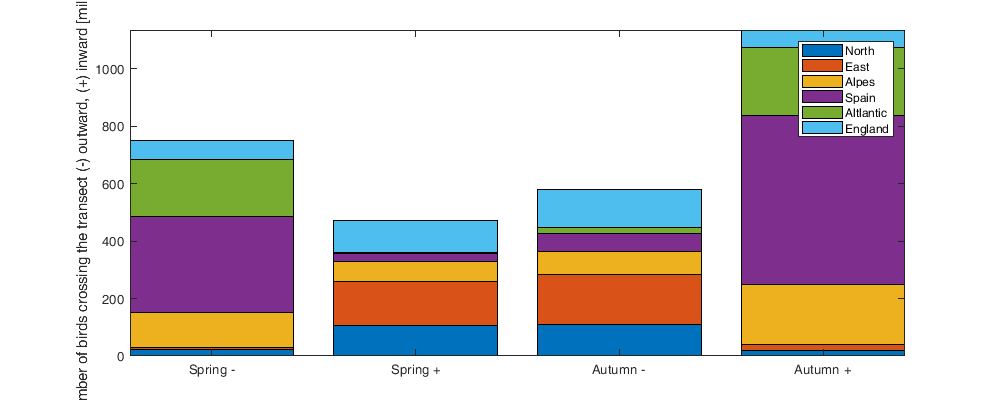

figure('position',[0 0 1000 400]); box on
bar(abs(mean(Fout_sec_season,3))'/1000000,'stacked'); axis tight
xticklabels({'Spring -', 'Spring +','Autumn -','Autumn +'})
ylabel('Number of birds crossing the transect (-) outward, (+) inward [millions]')
legend(transect_name)

Combining Spring entering and leaving and Autumn entering and leaving 

tmp = [sum(Fout_sec_season(:,1:2,:),2) sum(Fout_sec_season(:,3:4,:),2)]/1000000;

Spring and Autum (col) fluxes over the transects

var_name = {'Transect','MeanSpring','MeanAutumn','Q5Spring','Q95Spring','Q5Autumn','Q95Autumn','Ratio','Q5Ratio','Q95Ratio'};
table(transect_name',mean(tmp(:,1,:),3),mean(tmp(:,2,:),3),quantile(tmp(:,1,:),0.05,3),quantile(tmp(:,1,:),0.95,3),quantile(tmp(:,2,:),0.05,3),quantile(tmp(:,2,:),0.95,3),-mean(tmp(:,2,:)./tmp(:,1,:),3),-quantile(tmp(:,2,:)./tmp(:,1,:),0.05,3),-quantile(tmp(:,2,:)./tmp(:,1,:),0.95,3),'VariableNames',var_name)

ans = 6×10 table
     Transect      MeanSpring    MeanAutumn    Q5Spring    Q95Spring    Q5Autumn    Q95Autumn    Ratio     Q5Ratio    Q95Ratio
    ___________    __________    __________    ________    _________    ________    _________    ______    _______    ________

    'North'         -84.779        89.537      -88.822      -80.147      85.372       94.778     1.0564    1.0934      1.0178 
    'East'          -146.65        154.74      -152.99      -138.89      147.38       162.34     1.0554    1.0976       1.014 
    'Alpes'          55.481       -129.06       52.855       58.082     -134.96      -123.23     2.3274     2.464      2.2294 
    'Sp

Internal change

[
table(mean(sum(tmp([1 2 6],1,:),1),3),mean(sum(tmp([1 2 6],2,:)),3),quantile(sum(tmp([1 2 6],1,:)),0.05,3),quantile(sum(tmp([1 2 6],1,:)),0.95,3),quantile(sum(tmp([1 2 6],2,:)),0.05,3),quantile(sum(tmp([1 2 6],2,:)),0.95,3),-mean(sum(tmp([1 2 6],2,:))./sum(tmp([1 2 6],1,:)),3),-quantile(sum(tmp([1 2 6],2,:))./sum(tmp([1 2 6],1,:)),0.05,3),-quantile(sum(tmp([1 2 6],2,:))./sum(tmp(:,1,:)),0.95,3),'VariableNames',var_name(2:end));    
table(mean(sum(tmp(3:5,1,:),1),3),mean(sum(tmp(3:5,2,:)),3),quantile(sum(tmp(3:5,1,:)),0.05,3),quantile(sum(tmp(3:5,1,:)),0.95,3),quantile(sum(tmp(3:5,2,:)),0.05,3),quantile(sum(tmp(3:5,2,:)),0.95,3),-mean(sum(tmp(3:5,2,:))./sum(tmp(3:5,1,:)),3),-quantile(sum(tmp(3:5,2,:))./sum(tmp(3:5,1,:)),0.05,3),-quantile(sum(tmp(3:5,2,:))./sum(tmp(3:5,1,:)),0.95,3),'VariableNames',var_name(2:end));    
table(mean(sum(tmp(:,1,:),1),3),mean(sum(tmp(:,2,:)),3),quantile(sum(tmp(:,1,:)),0.05,3),quantile(sum(tmp(:,1,:)),0.95,3),quantile(sum(tmp(:,2,:)),0.05,3),quantile(sum(tmp(:,2,:)),0.95,3),-mean(sum(tmp(:,2,:))./sum(tmp(:,1,:)),3),-quantile(sum(tmp(:,2,:))./sum(tmp(:,1,:)),0.05,3),-quantile(sum(tmp(:,2,:))./sum(tmp(:,1,:)),0.95,3),'VariableNames',var_name(2:end))
]

ans = 3×9 table
    MeanSpring    MeanAutumn    Q5Spring    Q95Spring    Q5Autumn    Q95Autumn    Ratio     Q5Ratio    Q95Ratio
    __________    __________    ________    _________    ________    _________    ______    _______    ________

     -276.99         317.4      -287.82      -264.16      306.26       331.16     1.1462    1.1789     -1.2138 
      555.95       -874.12       531.29       581.94      -905.7      -839.81     1.5727    1.6126      1.5392 
      278.96       -556.72       263.57       295.18     -584.93      -526.69     1.9968     2.095      1.9278 


disp(['Density in Europe: ' num2str(mean(sum(tmp(3:5,2,:))/10/3*10)) ' birds/km^2'])

Density in Europe: -291.3718 birds/km^2


Sum of grouped transect

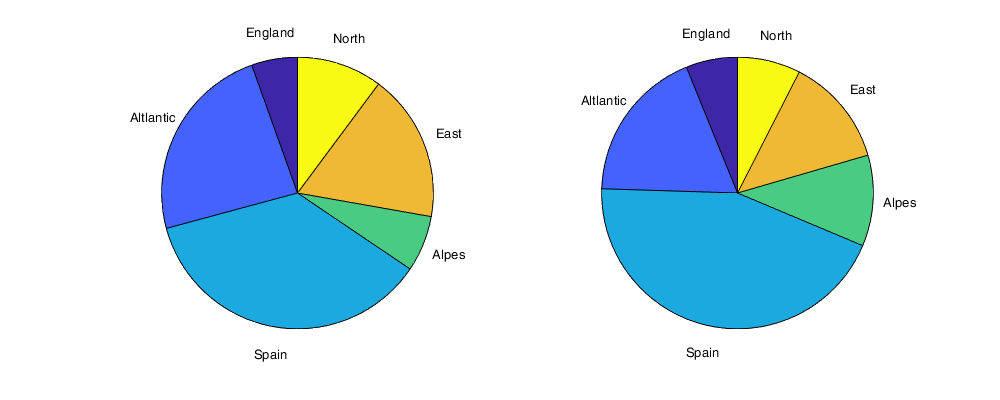

figure('position',[0 0 1000 400]);
subplot(1,2,1)
pie(flipud(abs(mean(tmp(:,1,:),3))),fliplr(transect_name))
subplot(1,2,2)
pie(flipud(abs(mean(tmp(:,2,:),3))),fliplr(transect_name))

## **Seasonal Flow: Within the study area**

dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]);
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]);
area = repmat(dx*dy,1,g.nlon);

Arrival/Departure over season

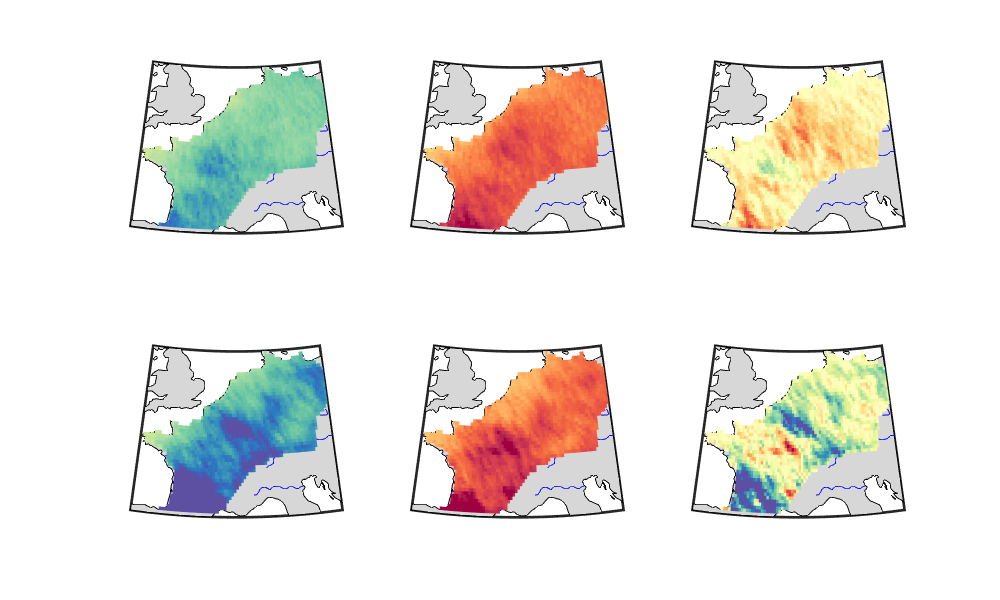

figure('position',[0 0 1000 600]); 
colormap(brewermap([],'Spectral'))
for i_s=1:2
    for i2=1:3
        subplot(2,3,(i_s-1)*3+i2); hold on
        h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue');
        caxis([-4000 4000])
        if i2==1
            W_tmp=nanmean(seasonal_W_takingoff(:,:,:,i_s),3);
        elseif i2==2
            W_tmp=nanmean(seasonal_W_landing(:,:,:,i_s),3);
        elseif i2==3
            W_tmp=nanmean(seasonal_W_takingoff(:,:,:,i_s)+seasonal_W_landing(:,:,:,i_s),3);
            caxis([-2000 2000])
        end
        surfm(g.lat2D,g.lon2D,W_tmp./area ); 
        %plotm(data.lat,data.lon,'.k'); 
    end
end